### Example 2: Real-world data

For this exercise, we will study whether we can find a good ARMA(p,q) model for spread.

We will consider four models: and ARMA(1,0), ARMA(1,1), ARMA(2,0) and an ARMA(2,1).

#### Step 1.1: Visualize the data

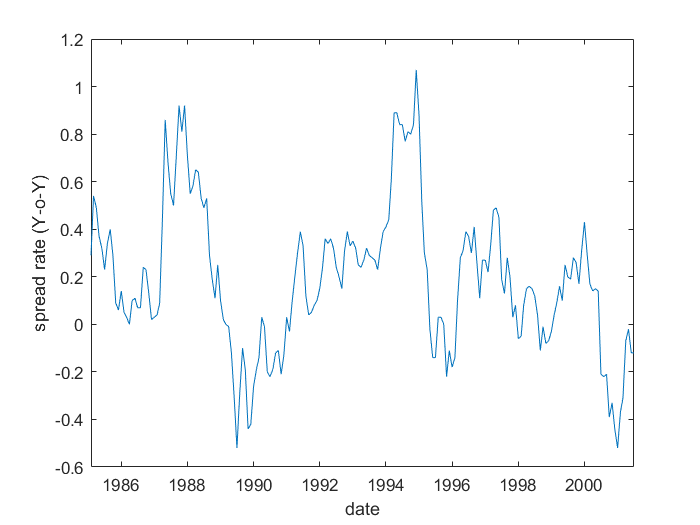

spread = spread_1y_3m;
dates = dates(sample);
plot(dates,spread)
xlabel('date')
ylabel('spread rate (Y-o-Y)')

#### Step 1.2: Evaluate the ACF and PACF

To establish if there is strong evidence of specific patterns that hints at the most appropriate ARMA order

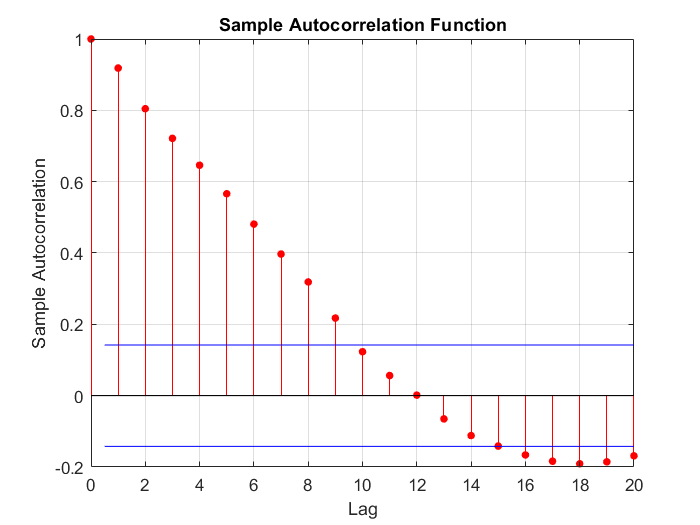

autocorr(spread)

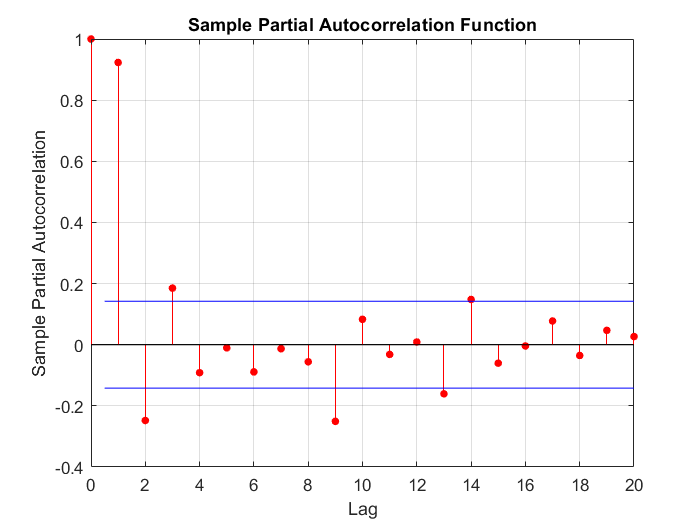

parcorr(spread)

#### Step 1.3: Select the most likely set of ARMA models

Compare these patterns to those described by Enders. Is there an obvious candidates? Does it correspond to what we know the true process is? Remember that Enders gives us the *theoretical *patterns. With noise as here, the fit will never be exact, but the patterns tend to be close to the theoretical ones. 

This series is very persistent, but with geometric decay in the ACF, suggesting an AR(p) process. The PACF shows a few significant values. The first two partial autocorrelations is what we will focus on (It is hard to motivate why the process should depend only on it's 11th and 13th lag and not the values in between). We will investigate a few ARMA models, but the most likely one to me seems to be an AR(2).

#### Step 2: Estimate the selected model(s)

In general, with real-world data, we would not want to take the risk of selecting the wrong model (in terms of ARMA orders) so would typically start with a set of potential models. For this simulated example, however, we can use the known structure and compare it to more/less flexible models directly

We again use the arima function to specify the model. There are a number of different ways to do it. Here I use the more explicit version as it is easier to read what is going on. We specify it as above, but replace the known parameters we chose above with NaN to indicate which coefficients should be estimated. We can also impose restrictions on certain coefficients by entering numbers. 

    postulated_model = arima('Constant',nan,'AR',{nan,nan,nan},'D',0)

postulated_model =   arima with properties:

     Description: "ARIMA(3,0,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 3
               D: 0
               Q: 0
        Constant: NaN
              AR: {NaN NaN NaN} at lags [1 2 3]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: NaN

    estimated_model = estimate(postulated_model,spread)

 
    ARIMA(3,0,0) Model (Gaussian Distribution):
 
                 Value      StandardError    TStatistic      PValue  
                ________    _____________    __________    __________

    Constant    0.013868      0.0098146         1.413         0.15765
    AR{1}         1.2045         0.0625        19.272      9.1605e-83
    AR{2}       -0.47494       0.099449       -4.7757      1.7911e-06
    AR{3}        0.19237       0.070438        2.7311       0.0063132
    Variance    0.012889      0.0012139        10.618      2.4591e-26



estimated_model =   arima with properties:

     Description: "ARIMA(3,0,0) Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 3
               D: 0
               Q: 0
        Constant: 0.013868
              AR: {1.20452 -0.474937 0.192371} at lags [1 2 3]
             SAR: {}
              MA: {}
             SMA: {}
     Seasonality: 0
            Beta: [1×0]
        Variance: 0.012889

#### Step 3: Evaluate model adequacy

Now we need to check whether the fitted model satisfies our requirements.

#### Step 3.1: Congruency

Does the estimated statistical model have the properties of the postulated statistical model? 

In our case, again, things are very simple. By construction, the functional form will be the one we postulated. What we need to check is the other assumptions

#### White noise, normally distributed residuals

Find the residuals from the estimation:

    residuals_spread = infer(estimated_model,spread);

Plot them against time:

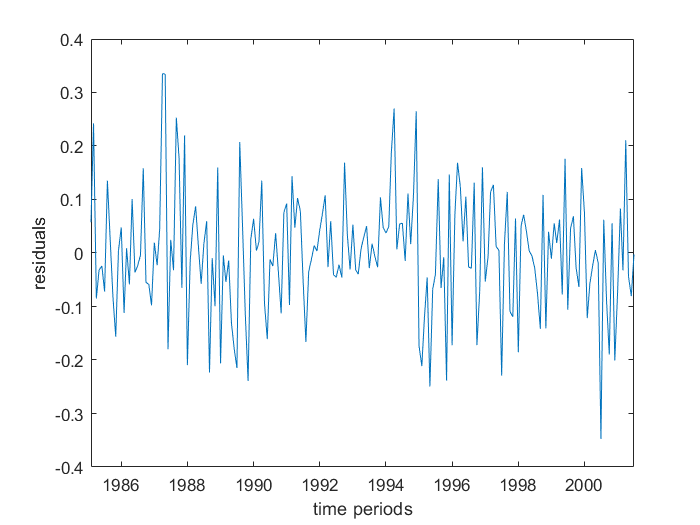

plot(dates,residuals_spread)
xlabel('time periods')
ylabel('residuals')

Evaluate their ACF and PACF:

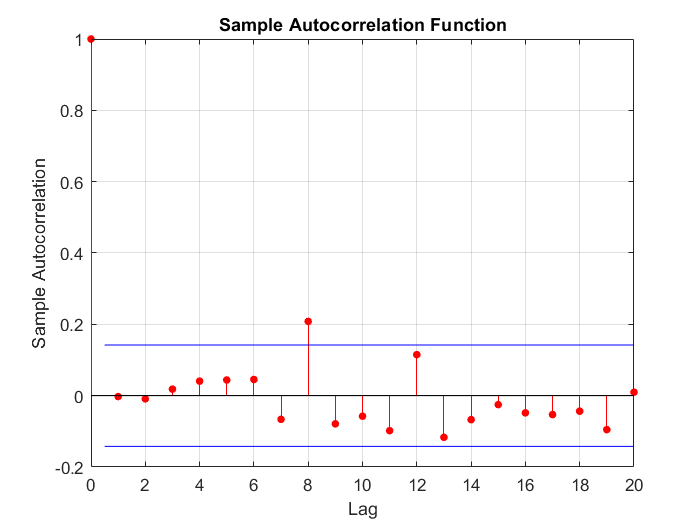

autocorr(residuals_spread)

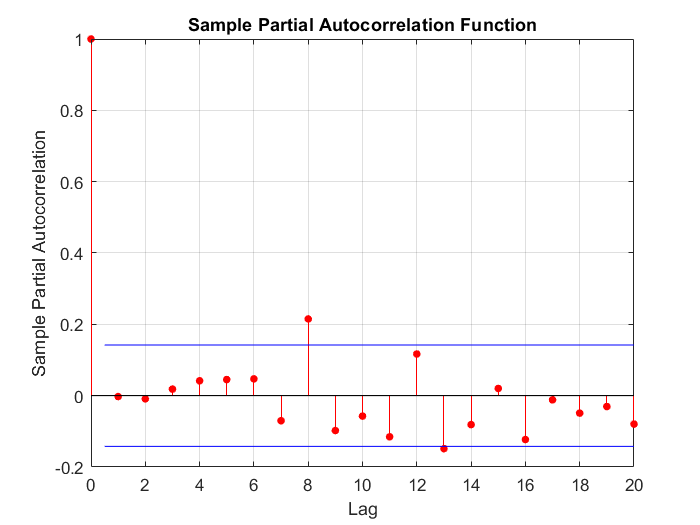

parcorr(residuals_spread)

Formally test for residual autocorrelation at a variety of lags using the Ljung-Box test statistic (must start larger than the AR order of the estimated model!)

The Matlab implementation of the Ljung-Box test has a number of different ways it can be used. See the help file and experiment. 

We need to specify the degrees of freedom and the lags at which we want to test the hypothesis.

lags = [2:12]; % select the lag or set of lags at which the test should be conducted
degrees_of_freedom = lags - 1; % sample size minus number of coefficients estimated other than the constant and variance
[reject_1,p_value_1] = lbqtest(residuals_spread,'Lags',lags,'DOF',degrees_of_freedom)

reject_1 = 1×11 logical array
   0   0   0   0   0   0   0   0   0   0   0


p_value_1 =     0.8966    0.9586    0.9354    0.9359    0.9408    0.9050    0.1306    0.1304    0.1541    0.1238    0.0805


Check for autocorrelation in squared residuals (this tests for homoscedasticity against and alternative of auto-regressive heteroscedasticity (ARCH effects):

[reject_2,p_value_2] = lbqtest(residuals_spread.^2,'Lags',lags,'DOF',degrees_of_freedom)

reject_2 = 1×11 logical array
   1   0   0   0   0   0   0   0   0   0   0


p_value_2 =     0.0200    0.0594    0.1219    0.0882    0.1498    0.2151    0.1481    0.1522    0.2143    0.2859    0.3213


In this empirical example, there is no reason to assume normality, unless we are relying on that for a specific test (which we are not doing today). Nevertheless, we can see whether the errors are statistically normal:

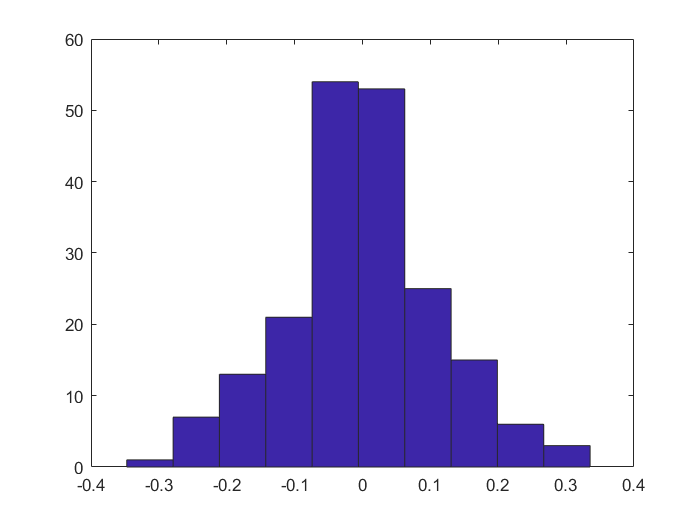

hist(residuals_spread)

[reject_normality,p_value_normality,jbstat,critval] = jbtest(residuals_spread)

reject_normality = 0

p_value_normality = 0.2945

jbstat = 2.1167

critval = 5.6756

#### Step 3.2. Parsimony

We have a number of models that are very similar in terms of how congruent they are. Let's compare their relative parsimony using the Akaike and Bayesian Information Criteria

postulated_model_ARMA10 = arima('Constant',nan,'AR',{nan},'D',0);
postulated_model_ARMA11 = arima('Constant',nan,'AR',{nan},'MA',{nan},'D',0);
postulated_model_ARMA20 = arima('Constant',nan,'AR',{nan,nan},'D',0);
postulated_model_ARMA21 = arima('Constant',nan,'AR',{nan,nan},'MA',{nan},'D',0);

logL = zeros(4,1); % Preallocate loglikelihood vector
[~,~,logL(1)] = estimate(postulated_model_ARMA10,spread,'Display','off');
[~,~,logL(2)] = estimate(postulated_model_ARMA11,spread,'Display','off');
[~,~,logL(3)] = estimate(postulated_model_ARMA20,spread,'Display','off');
[~,~,logL(4)] = estimate(postulated_model_ARMA21,spread,'Display','off');


The syntax for the test is:

[`[aic,bic] = aicbic(logL,numParam,numObs)`](https://localhost:31515/static/help/econ/aicbic.html#d120e96188)


[aic,bic] = aicbic(logL, [3; 4; 5; 6], length(spread)*ones(4,1))

aic =  -273.8455
 -290.6547
 -282.6216
 -287.8685


bic =  -263.9807
 -277.5016
 -266.1802
 -268.1389


Both tests select the ARMA(1,1) model.

P = [0,1,2];
[P,Q] = meshgrid(P);
LogL = NaN(3);
numPar = P+Q;

for p=1:3
    for q=1:3
        Mdl = regARIMA(p-1,0,q-1);
        [~,~,LogL(p,q)]=estimate(Mdl,spread,'Display','off');
    end
end

[~,bic] = aicbic(LogL(:),numPar(:)+2,length(spread)-max(P(:),Q(:)))

bic =   104.5282
 -263.9959
 -271.5091
  -89.3675
 -277.5219
 -273.4779
 -181.7683
 -274.2019
 -269.2184



BIC = reshape(bic,3,3)

BIC =   104.5282  -89.3675 -181.7683
 -263.9959 -277.5219 -274.2019
 -271.5091 -273.4779 -269.2184



minbic = min(bic)

minbic = -277.5219


[imax jmax] = find(BIC==minbic)

imax = 2

jmax = 2


OptMdl = regARIMA(1,0,1)

OptMdl =   regARIMA with properties:

     Description: "ARMA(1,1) Error Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
       Intercept: NaN
            Beta: [1×0]
               P: 1
               Q: 1
              AR: {NaN} at lag [1]
             SAR: {}
              MA: {NaN} at lag [1]
             SMA: {}
        Variance: NaN

est_optMdl = estimate(OptMdl,spread)

 
    ARMA(1,1) Error Model (Gaussian Distribution):
 
                   Value      StandardError    TStatistic      PValue   
                 _________    _____________    __________    ___________

    Intercept    -0.019683        0.08688       -0.22655         0.82077
    AR{1}          0.86707       0.034541         25.102     4.6708e-139
    MA{1}          0.38573       0.069775         5.5283      3.2335e-08
    Variance      0.012956      0.0012155         10.658      1.5944e-26



est_optMdl =   regARIMA with properties:

     Description: "ARMA(1,1) Error Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
       Intercept: -0.0196826
            Beta: [1×0]
               P: 1
               Q: 1
              AR: {0.867069} at lag [1]
             SAR: {}
              MA: {0.385734} at lag [1]
             SMA: {}
        Variance: 0.0129555


    residuals_spread = infer(estimated_model,spread);

Plot them against time:

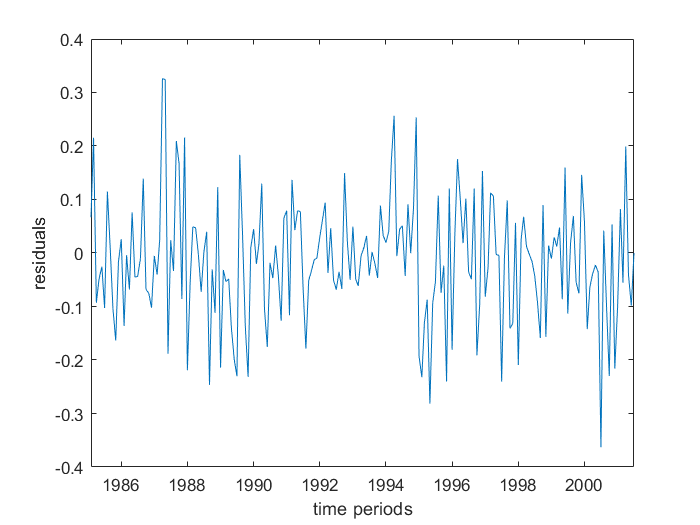

plot(dates,residuals_spread)
xlabel('time periods')
ylabel('residuals')

Evaluate their ACF and PACF:

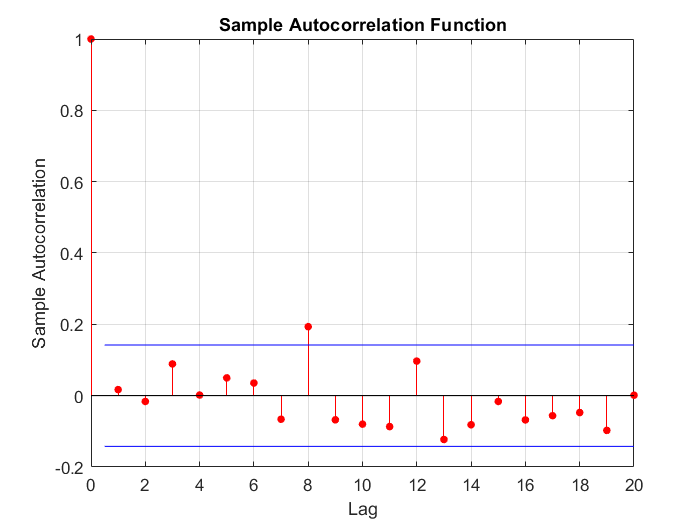

autocorr(residuals_spread)

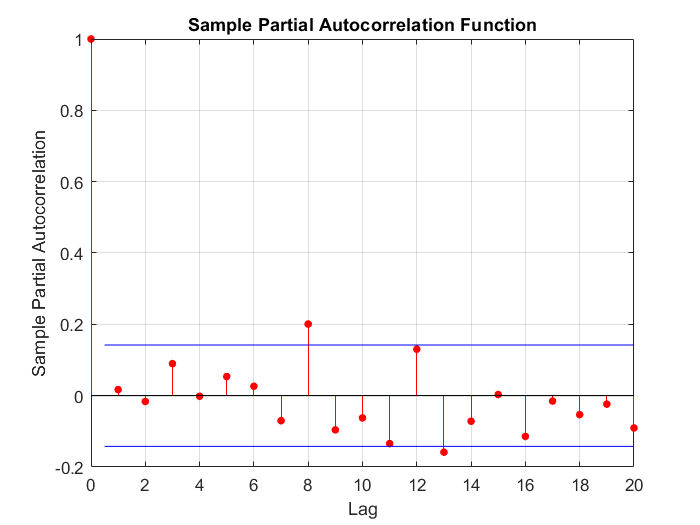

parcorr(residuals_spread)

Formally test for residual autocorrelation at a variety of lags using the Ljung-Box test statistic (must start larger than the AR order of the estimated model!)

The Matlab implementation of the Ljung-Box test has a number of different ways it can be used. See the help file and experiment. 

We need to specify the degrees of freedom and the lags at which we want to test the hypothesis.

lags = [2:12]; % select the lag or set of lags at which the test should be conducted
degrees_of_freedom = lags - 1; % sample size minus number of coefficients estimated other than the constant and variance
[reject_1,p_value_1] = lbqtest(residuals_spread,'Lags',lags,'DOF',degrees_of_freedom)

reject_1 = 1×11 logical array
   0   0   0   0   0   0   0   0   0   0   0


p_value_1 =     0.7388    0.4232    0.6324    0.6934    0.7781    0.7577    0.1304    0.1446    0.1415    0.1291    0.1053


Check for autocorrelation in squared residuals (this tests for homoscedasticity against and alternative of auto-regressive heteroscedasticity (ARCH effects):

[reject_2,p_value_2] = lbqtest(residuals_spread.^2,'Lags',lags,'DOF',degrees_of_freedom)

reject_2 = 1×11 logical array
   1   0   0   0   0   0   0   0   0   0   0


p_value_2 =     0.0474    0.1186    0.2304    0.2264    0.3399    0.4607    0.3839    0.3158    0.3894    0.4803    0.4751


In this empirical example, there is no reason to assume normality, unless we are relying on that for a specific test (which we are not doing today). Nevertheless, we can see whether the errors are statistically normal:

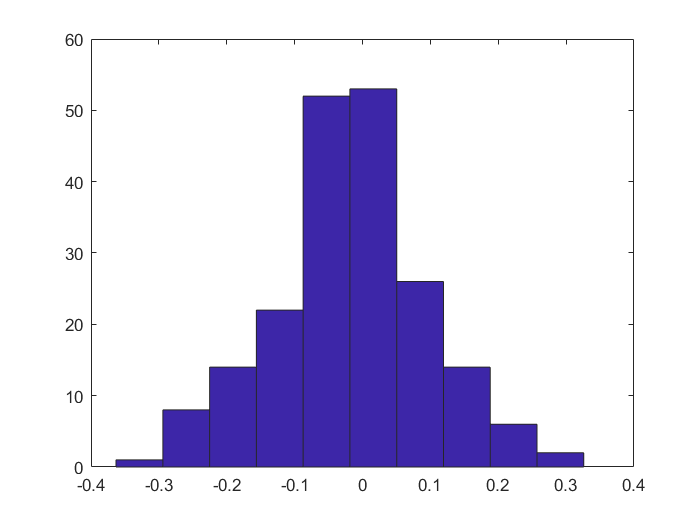

hist(residuals_spread)

[reject_normality,p_value_normality,jbstat,critval] = jbtest(residuals_spread)

reject_normality = 0

p_value_normality = 0.2961

jbstat = 2.1076

critval = 5.6756